# Informe Laboratorio: Análisis Numérico

# Práctica No. 2

**Juan Pablo Jiménez Gómez **

**Código: 2173051**

**Grupo: B2**

*Escuela de ingeniería de sistemas e informática*

*Universidad Industrial de Santander*

19 de Noviembre de 2020

## 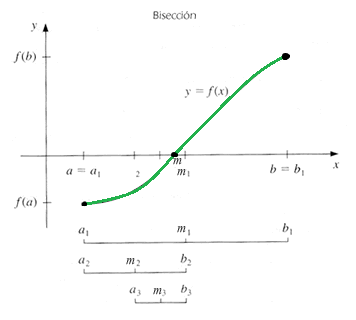

**Figura 1.1: Metódo de bisección**

## **Introduction:**

In the next laboratory we will work on the Matlab application we will work with the bisection method, which is a root search algorithm whose purpose is to divide the proposed interval in half and select the subinterval that has the root. Our knowledge will be put to the test with questions on the subject, and practical exercises, and different codes will be programmed with the purpose of evaluating the different functions required in subsequent exercises, which must work with specific intervals and iterations.

## **3. Practice**

**3.1 Understanding**

**Answer with your own words the following questions:**

- **(0.2 points) Explain briefly what the bisection method is.**

Being widely used for solving one-variable equation exercises, the bisection method has been an algorithm for searching for roots. This theorem establishes that every continuous function f that is being worked within a specific interval [a, b] as it should take values that are between the points f (a) and f (b). The previous approach is due to the fact that the value, or the different values taken from f (a) and f (b), is the image of a value of the interval [a, b] where ∃ 𝑥:𝑓(𝑥)=0.

- **(0.2 points) What condition do the initial points a and b have to satisfy to be used in the bisection method?**

so that the bisection method can be determined, both values of the function both f (a) and f (b) have opposite signs each, with the purpose of determining the intermediate value between them, and in such a way that there is a p in [a, b] that satisfies f (p) = 0

- **(0.2 points) Describe the decision step at each iteration for the bisection method.**

1) We determine the interval in [𝑎, 𝑏] that we are going to use for the procedure, and that fulfills that 𝑓 (𝑎) ∗ 𝑓 (𝑏) <0

2) You must find that value that is in the middle of the interval a point x with which you are working

3) After this, a replacement is made either by the value of a or b, taking into account that 𝑓 (𝑐) ∗ 𝑓 (𝑏) <0 or 𝑓 (𝑎) ∗ 𝑓 (𝑐) <0

4), It is necessary to take into account with which case and which conditions are used, however finally it must be taken into account that c is replaced, that is, we make a change replacing either a by c in the same way b by c, from successively taking into account that it can be iterated as many times as necessary.

- **(0.2 points) What applications does the bisection method have?**

Taking into account the question that was asked above, starting from this new interval, we continue successively closing the space that defines the solution in a smaller and smaller interval, in such a way that the desired precision can be found.

There are two cases that apply to the calculation of the bisection method, with the first it is described that when p is equal to 0, or less to the implementation or tolerance. The method has already defined its root in the interval worked or a very close one. For the second case it is necessary that if the method exceeds the number of iterations, therefore it was not possible to determine the root of the interval with the initial number of iterations that occurred in the interval [a, b]. For applications, the Newton method is much more effective than the bisection method, however with the latter the convergence of the function that is being determined can be guaranteed. If we have that f is a continuous function on [a, b] and f (a) f (b) <0, then this method converges to the root of f.

Some of the most popular applications of this method have been: calculation of individual members of families of periodic orbits, automatic improvement of behavior of the ASO algorithm, and the computation of individual members of families of periodic orbits

**3.2 Applying**

(0.4 points) Use the Bisection method to findnd the root of the function f(x) = $\tan^2$(x)-x on [1:8; 3]. Choose two appropriate initial points a and b. Do have iterations by hand.

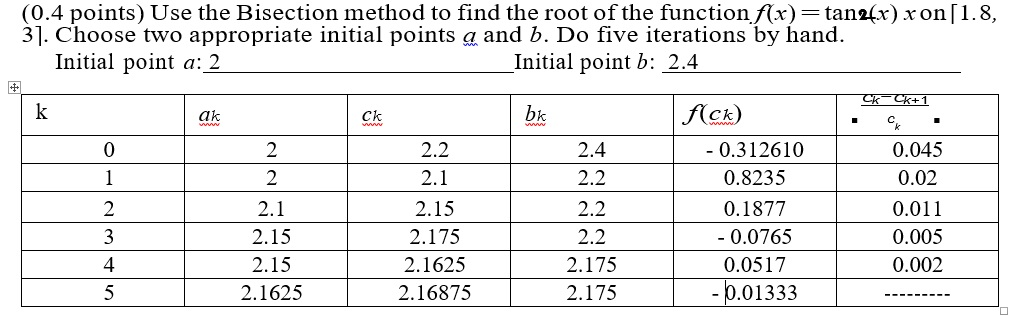

**3.3 Implementing**

- (0.7 points) Create a Matlab function called my_finding_interval_name_lastname() to find two adequate initial points [a, b] given a function f(x). Make a script called run_2a_name_lastname.m in which you use the created function with an example (start the search at 0).

Myfun = @(x)(tan(x).^2)-x ;
[a, b] = my_finding_interval_Juan_Pablo_Jimenez_Gomez(Myfun);
a

a = -3

b

b = 3

**analysis:** For the first exercise, we are asked to create a function with which we must find the appropriate intervals  [a, b], given a certain function f (x), having said this, the first thing to do is define the variables by describing the value of the function which will be (tan(x).^2)-x being the same as the previous exercise, and points a and b will be programmed. In the part of the annex that can be found at the end of the laboratory, what was done was to initialize the points x, y in 0 in such a way that if the multiplication of both is greater than or equal to 0. After this, the range is defined of numbers to be taken, and the randi function is used to take a single uniformly distributed random number. Finally we save the temporary for the case where a> b thus completing the purpose of the exercise

- (0.8 points) Create a Matlab function called my_bisection_function_name_lastname() to find the root of a function. The arguments of the function must be: the function to be evaluated f(x) (as an inline function), the initial points [a, b], and the stopping criteria (the number of iterations or the relative error). Make a script called run_2b_name_lastname.m in which you use the created function to solve any example. For instance.

fun = @ XXXXXX;

a=XX;

b=XX;

Iter=X;

root=my bisection function name lastname(fun,a,b,Iter);

fun= @(x) (tan(x).^2)-x;
a=2.1;
b=2.2;
iter=10;
root= my_bisection_function_Juan_Pablo_Jimenez_Gomez(fun,a,b,iter)

root = 2.1675

**analysis:** For this second exercise we are asked to find the root of a function. For this reason f (x) must be evaluated, and the initial interval points [a, b], the number of iterations and the relative error. First, the variables are defined, and the function with which it is going to work, the value of the interval a and b. Then from this the first thing is to generate the random root, to then assign the respective iterations of k, and implement c in such a way that it is the sum of a and b divided in two in order to determine the intermediate point of the function that will be greater than 0

- (0.7 points) Given the function f(x) = (x − 8)(x − 3)^2 use your script to find each one of the roots. Compare the theoretical number of iterations N with respect to the practical number of iterations when the stopping criteria is established as 𝜖=1$e^{-2}$,1$e^{-4}$,1$e^{-6}$,1$e^{-8}$,1$e^{-10}$. Plot the results where the x-label corresponds to the value of epsilon, and the y-label corresponds to the number of iterations for both cases: theoretical and practical. Conclude about the figure.

clear all
close all
clc
fun = @(x)(x-8).*((x-3).^2);
k = 1;
for i = 2:2:10
    e = exp(-i);
    [root, teorical_val(k), experimental_val(k)] = my_bisection_function_Juan_Pablo_Jimenez_Gomez_z(fun, e); 
    k=k+1;
end
g = [teorical_val; experimental_val]'; 
x = 2:2:10; 
bar(x,g);
root

root = 19

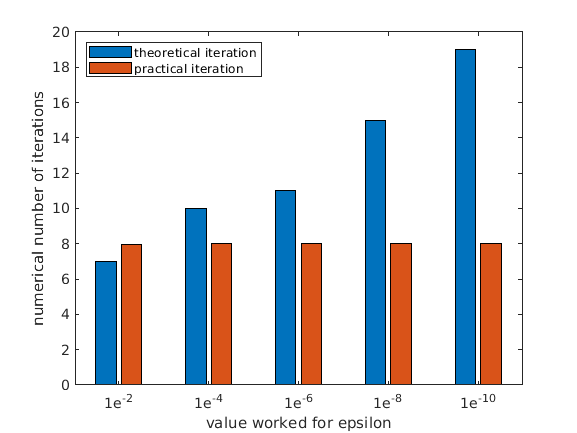

ylabel('numerical number of iterations');
xlabel('value worked for epsilon');
legend('theoretical iteration', 'practical iteration', 'Location', 'northwest');
mistakes = {'1e^{-2}';'1e^{-4}';'1e^{-6}';'1e^{-8}';'1e^{-10}'};
set(gca,'xtick',x,'xticklabel',mistakes);

**analysis:** For this exercise, taking into account the function  (x-8).*((x-3).^2) a function must be programmed in such a way that it seeks to find each one of the roots, after this the theoretical value of iterations must be compared with respect to the practical number of these, and graph from these the respective result. The first thing to do is define the variables to be used, and after that program the code so that the values for the theoretical iterations "teorical_val" and the values for the practical iterations "experimental_val" are saved. Following the previous step, we join both vectors since we are trying to create a matrix by programming g. In order to create the graph we take the transpose, and define x to determine the interval o of errors. Finally, the elements of the graph, the titles of each section and the percentages, errors and both theoretical and practical values of the function are programmed.

From the graph we can intuit that if the worked value of epsilon is less, then the number of iterations will be greater. In addition, the number of iterations of the theoretical value with respect to the practical one is greater

- (0.8 points) Create a Matlab function called my_visual_bisection_function_name_lastname() to visualize the behaviour of the Bisection method. The arguments of the function must be: the function to be evaluated f(x) (as an inline function), the initial points [a, b], and the number of iterations. Make a script called run_2d_name_lastname.m in which you use the created function to visualize the behavior of the bisection method when solving any example and conclude about the convergence of the method For instance.

fun = @ XXXXXX;

a=XX;

b=XX;

Iter= XX

P=my visual bisection function name lastname(fun,a,b,Iter);

Myfun = @(x)(tan(x).^2)-x; 
a=2;
b=2.4;
iter = 11;
[Va, Vb] = my_visual_bisection_function_Juan_Pablo_Jimenez_Gomez(Myfun,a,b,iter); 
x = -10:0.01:10; 
y = (tan(x).^2)-x

y = 	1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


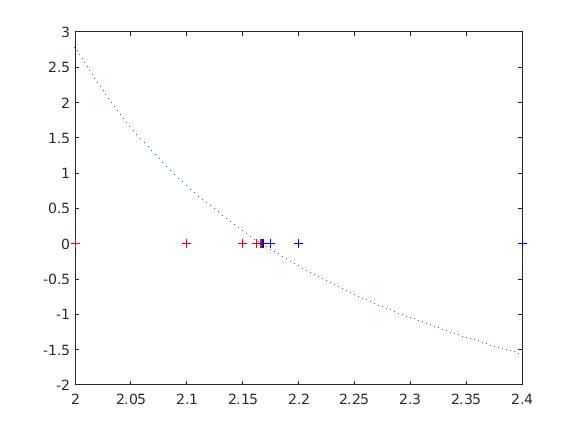

plot(x,y,':');
hold on
plot(Va, 0, 'r:+');
plot(Vb,0,'b:+');
xlim([a b]);

**analysis:**  For the following exercise, a function was created to be able to visualize the type of behavior that the bisection method has for the proposed function. We have that f (x) that is, the function that is evaluated must be an online function. We define a number of iterations for the function, and when defining the variables, and the values for the intervals [a b], the vector a "Va" and the vector b "Vb" are taken so that in this way the points are returned a and b for each iteration, so that its behavior can be appreciated. In order to graph the function, x is defined as the intervals to be worked on. After that, the vectors a and b are drawn, and the points that they are going to take on the graph.

From the graph we can see that regarding the advance of the iterations, the worked points a and b come together little by little, which leads us to conclude that they are closer to point c in such a way that the function f (c) is fulfilled = 0 and the exercise is completed.

**3.3 Interpreting**

When the mortality rate is neglected, the world population 𝑁 can be simulated by a function that grows in proportion to the number of individuals existing at any time t. Also, if λ is the growth rate, 𝜑 is a coefficient that simulates the immigration, and $N_0$ is the population at the beginning of the simulation, the function to determine the quantity of individuals at any time t is given by

## 𝑁(𝑡)=$N_0$$e^{\lambda t}$+𝜑$\frac{e^{\lambda t} -1}{\lambda }$

Assume that in t=0 the world population has 1500 individuals, also assume that the inmigriation rate is of 475 individuals per year, and after one year (t=1 )the population has amounted to 2264 individuals

- Determine a nonlinear equation 𝑓(𝜆)=0 to calculate the growth rate 𝜆 by finding its root.

## N(𝑡)=$N_0$$e^{\lambda t}$+𝜑$\frac{e^{\lambda t} -1}{\lambda }$   ==> 1500 = $N_0$$e^{\lambda t\left(0\right)}$+475 * $\frac{e^{\lambda t\left(0\right)} -1}{\lambda }$   ==> 1500 = N

## 2264 = 1500 * $e^{\lambda t}$ + 475 * $\frac{e^{\lambda t} -1}{\lambda }$ ==> Bisection Method ==> 0 = 1500 * $e^{\lambda t}$ + 475 * $\frac{e^{\lambda t} -1}{\lambda }$ - 2264

- Make a script to find the root of the nonlinear equation 𝑓(𝜆)=0 by using the created function in 3.3. Also plot the function between λ=0.001 and λ=1.

Myfun = @(x) ((1500.*exp(x)+(475*((exp(x)-1)./(x)))-2264)); 
a=0.001;
b=1;
iter = 20;
[Va, Vb] = my_visual_bisection_function_Juan_Pablo_Jimenez_Gomez(Myfun,a,b,iter); 
x = -10:0.01:10; 
y = ((1500.*exp(x)+(475*((exp(x)-1)./(x)))-2264));
raiz = my_bisection_function_Juan_Pablo_Jimenez_Gomez(Myfun,a,b,iter)

raiz = 0.1544

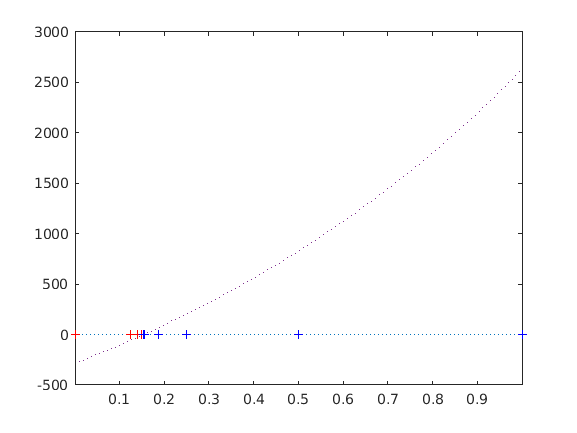

plot(x,y,':');
hold on
plot(Va, 0, 'r:+');
plot(Vb,0,'b:+');
xlim([a b]);

**analysis: **According to the problem of applying the mortality rate where they tell us that there is a world population N and that there are a portion of individuals at an instant t. 𝜆 is the growth rate and 𝜑 is a coefficient used for migration, and $N_0$ is the initial population. That said, we have that at a time equal to 0 and that the population has 1500 individuals, the immigration rate is 475 per year, and that after one year (t = 1) the population rises to 2264 individuals. Having given feedback on the information, the exercise asks us for a function to determine the root of the equation f (𝜆) = 0 using the function given in the statement, and that also tells us that 𝜆= 0.001  and 𝜆 = 1. So the first thing is to propose the function proposed by the exercise before and after that define the two intervals, a = 0.001 and b = 1. In addition, we take the number of iterations, and define [Va, Vb] as the vectors with which we are going to work in such a way that the points a and b of the iterations are returned in order to appreciate their behavior. We define x as the interval to work for the graph, in addition to using y as the proposed function. After this we define what values for the vectors are going to take and finally we define the value of the root. in such a way that it is appreciated that a and b come together more in that intermediate point worked, that is, that point c, from which it can be said that the purpose of the exercise is achieved.

## Annexes

Function for the Matlab exercise  my_finding_interval_Juan_Pablo_Jimenez_Gomez

function [a,b] = my_finding_interval_Juan_Pablo_Jimenez_Gomez(funcion)
X = 0; 
Y = 0;
while(X*Y>=0)
    a = randi([-10 10],1,1);
    b = randi([-10,10],1,1);
    X = funcion(a);
    Y = funcion(b);
end
if (a>b)
    temp = a;
    a = b;
    b = temp;
end
end



Function for the matlab exercise my_bisection_point_Juan_Pablo_Jimenez_Gomez


function [root] = my_bisection_function_Juan_Pablo_Jimenez_Gomez(fun,a,b,iter)
for k = 1:iter
    c = (a+b)/2;
    if (fun(c)*fun(b)>0)
        b = c;
    else
        a = c;
    end
    root = c;
end 
end

Function for the Matlab exercise my_bisection_point_Juan_Pablo_Jimenez_Gomez_z

function[teorical_val, practical_val,root] =  my_bisection_function_Juan_Pablo_Jimenez_Gomez_z(fun, delta)
[a,b] = my_finding_interval_Juan_Pablo_Jimenez_Gomez(fun);
practical_val = 0;
teorical_val= 1 + round((log(abs(b-a))-log(delta))/log(2));
for k = 1:teorical_val
    c = (a+b)/2;
    if(fun(c)*fun(b)>0)
        b = c;
    else
        a = c;
    end
    root = c;
    practical_val = practical_val+1;
    if(abs(b-a)<delta)
        return;
    end
end
end

Function my_visual_bisection_function_Juan_Pablo_Jimenez_Gomez

function [point_A,point_B] = my_visual_bisection_function_Juan_Pablo_Jimenez_Gomez(fun,a,b,iter)
i = 1;
for k = 1:iter
    point_A(i) = a;
    point_B(i) = b;
    i=i+1;
    c=(a+b)/2;
    if (fun(c)*fun(b)>0)
        b=c;
        point_B(i) = b;
    else
        a = c;
        point_A(i)=a;
    end
    root=c;
end
end